# **Decimation and Interpolation of Audio Signals   **

Multirate Digital Signal Processing- EE6133

Aug-Nov 2021, IIT Madras

Experiment 1

Author: Arjun Menon Vadakkeveedu, ee18b104

October 2021

Link to the git repository hosting the code, input and output files: [github link](https://github.com/arjunmenonv/AudioMultirateProc)

## Part 1: Downsampling without Anti-Alias Filtering

#### 1.1 Read input files, play back and plot Magnitude Response

[audio16k, Fs_audio] = audioread('inp/music16khz.wav');
[speech8k, Fs_speech] = audioread('inp/speech8khz.wav');
disp(['Original Audio Signal Sampling Rate: ', num2str(Fs_audio), 'Hz']);

Original Audio Signal Sampling Rate: 16000Hz


disp(['Original Speech Signal Sampling Rate: ', num2str(Fs_speech), 'Hz']);

Original Speech Signal Sampling Rate: 8000Hz


% Playing the .wav files at original Sampling Rates
player1 = audioplayer(audio16k, Fs_audio);
player2 = audioplayer(speech8k, Fs_speech);
playblocking(player1);
playblocking(player2);

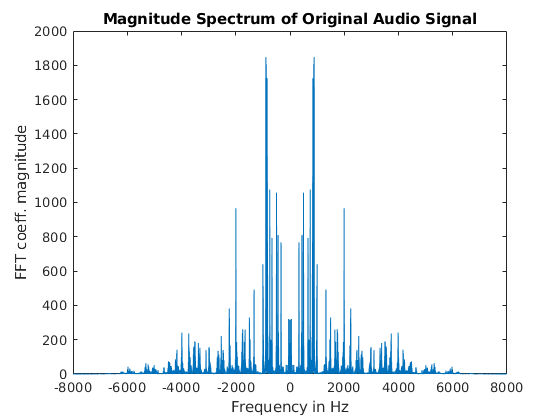

%Magnitude Response of Original Signals
Naudio = 2^(ceil(log2(length(audio16k))));
Nspeech = 2^(ceil(log2(length(speech8k))));
fft_audio = fftshift(fft(audio16k, Naudio));
fft_speech = fftshift(fft(speech8k, Nspeech));
wAudio = linspace(-Fs_audio/2, Fs_audio/2, Naudio);
wSpeech = linspace(-Fs_speech/2, Fs_speech/2, Nspeech); 
figure();
plot(wAudio, abs(fft_audio));
xlabel("Frequency in Hz");
ylabel("FFT coeff. magnitude");
title("Magnitude Spectrum of Original Audio Signal");

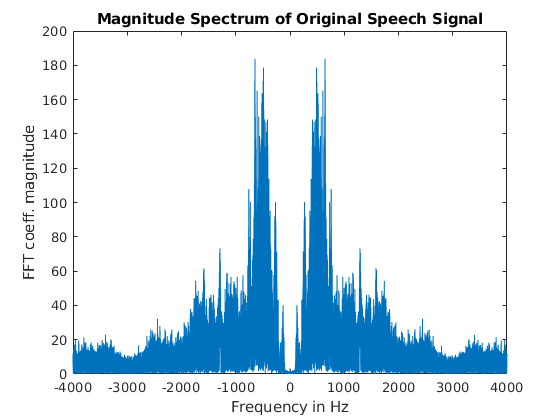

figure();
plot(wSpeech, abs(fft_speech));
xlabel("Frequency in Hz");
ylabel("FFT coeff. magnitude");
title("Magnitude Spectrum of Original Speech Signal");

#### 1.2 Downsample by 2, play back and generate Magnitude Response

The generated audio files are saved to the location out/<originalFileName>-D2.wav

The signal {x[n]} is downsampled as

 $\{x_d[n]\} = x[Mn]

$, where M is the downsampling factor

%Downsampling by 2
M = 2;
%M = 4;
audioDown = audio16k(1:M:end);
speechDown = speech8k(1:M:end);
Fs_audioD = Fs_audio/M;
Fs_speechD = Fs_speech/M;
player1 = audioplayer(audioDown, Fs_audioD);
player2 = audioplayer(speechDown, Fs_speechD);
playblocking(player1);
playblocking(player2);
audiowrite('out/music16k-D2.wav', audioDown, Fs_audioD);
audiowrite('out/speech8k-D2.wav', speechDown, Fs_speechD);

**Inference:**

There is a clear reduction in the 'quality' of the audio signals (both music and speech) when the original signal is downsampled. For M=2, the reduction in quality due to aliasing is more pronounced for the speech signal while for M = 4, the distortions in both music and speech are evident even to the untrained ear. 

The following cell plots the magnitude spectra of the downsampled signal (default: M =2). To generate the spectrum for M = 4, uncomment the "%M = 4;" line in the previous cell.

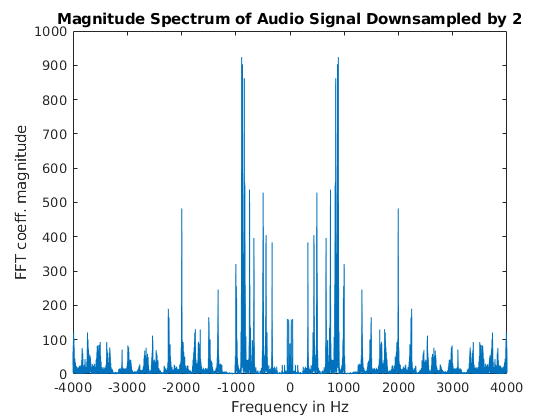

%Magnitude Spectrum of Downsampled Signals
NaudioD = 2^(ceil(log2(length(audioDown))));
NspeechD = 2^(ceil(log2(length(speechDown))));
fft_audioD = fftshift(fft(audioDown, NaudioD));
fft_speechD = fftshift(fft(speechDown, NspeechD));
wAudio = linspace(-Fs_audioD/2, Fs_audioD/2, NaudioD);
wSpeech = linspace(-Fs_speechD/2, Fs_speechD/2, NspeechD); 
figure();
plot(wAudio, abs(fft_audioD));
xlabel("Frequency in Hz");
ylabel("FFT coeff. magnitude");
title("Magnitude Spectrum of Audio Signal Downsampled by 2");

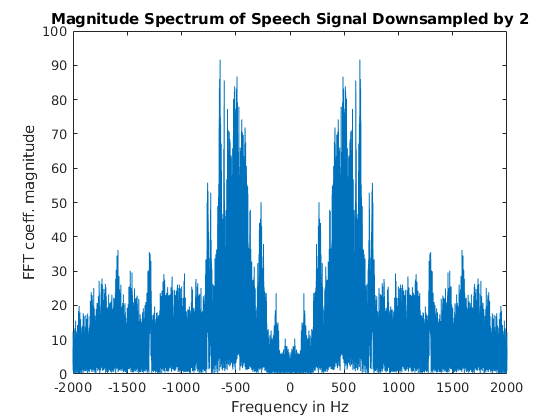

figure();
plot(wSpeech, abs(fft_speechD));
xlabel("Frequency in Hz");
ylabel("FFT coeff. magnitude");
title("Magnitude Spectrum of Speech Signal Downsampled by 2");

## Part 2: Equiripple Filter Design and Downsampling with AAF

#### 2.1 Equiripple Filter Design

Using Parks-McClellan optimal FIR filter design (firpm API) to design an AAF (low-pass filter) with cutoff at $\frac{\pi}{2}$

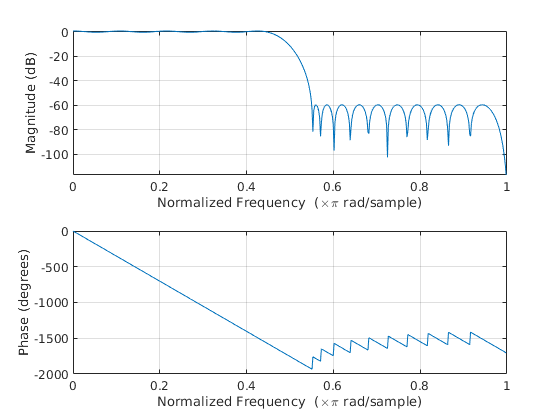

cutoff = [0.45*pi, 0.55*pi];
% Passband and Stopband Ripples in dB
rpass = 1;  
%rstop = -30; 
rstop = -60;    % Vary rstop to see if "stronger" filters have significant impact
filtFreqAudio = cutoff*Fs_audio/(2*pi);
filtFreqSpeech = cutoff*Fs_speech/(2*pi);
a = [1, 0];     % Desired amplitudes at the passband and stopband frequencies
dev = [(10^(rpass/20) - 1)/(10^(rpass/20) + 1), 10^(rstop/20)];
[n, fo, ao, w] = firpmord(filtFreqAudio, a, dev, Fs_audio);
bAudio = firpm(n, fo, ao, w);
[n, fo, ao, w] = firpmord(filtFreqSpeech, a, dev, Fs_speech);
bSpeech = firpm(n, fo, ao, w);
freqz(bAudio);

#### 2.2 Downsampling after Anti-Alias Filtering

audioAA = filter(bAudio, 1, audio16k);
speechAA = filter(bSpeech, 1, speech8k);
M  = 2;
%M  = 4;
audioAAD = audioAA(1:M:end);
speechAAD = speechAA(1:M:end);
Fs_audioD = Fs_audio/M;
Fs_speechD = Fs_speech/M;
player1 = audioplayer(audioAAD, Fs_audioD);
player2 = audioplayer(speechAAD, Fs_speechD);
playblocking(player1);
playblocking(player2);
audiowrite('out/music16k-AAD2.wav', audioDown, Fs_audioD);
audiowrite('out/speech8k-AAD2.wav', speechDown, Fs_speechD);

**Inference**

The anti-aliasing filter helps reduce aliasing in the downsampled signals. As a result, the audio quality of these signals is better than that of vanilla Downsampling (without AAF). However, for M = 4, the resultant audio signals have significant distortion. 

It is also noticed upon trying various values for the stopband ripple (-10 dB, -30 dB, -60 dB) that the stopband ripple did not have a significant impact on the quality of the audio signal. Since M = 2 is not satisfactory, the next option is to downsample by a fraction => upsampling followed by downsampling (or vice versa).

The following cells plots the magnitude response of the audio and speech signals for the above case (AAF followed by Downsampling by 2).

#### 2.3 Magnitude Spectrum of Signals Downsampled after AAF

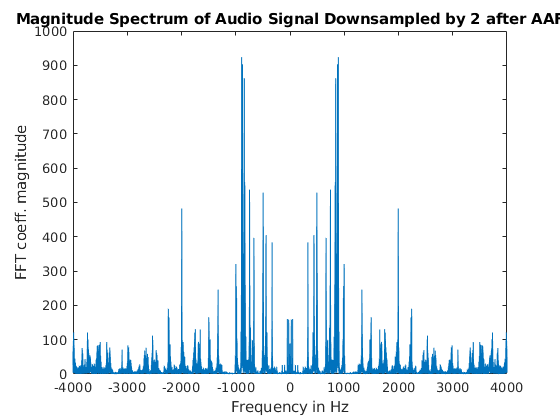

%Magnitude Spectrum of AAD Signals
fft_audioAAD = fftshift(fft(audioAAD, NaudioD));
fft_speechAAD = fftshift(fft(speechAAD, NspeechD));
wAudio = linspace(-Fs_audioD/2, Fs_audioD/2, NaudioD);
wSpeech = linspace(-Fs_speechD/2, Fs_speechD/2, NspeechD); 
figure();
plot(wAudio, abs(fft_audioD));
xlabel("Frequency in Hz");
ylabel("FFT coeff. magnitude");
title("Magnitude Spectrum of Audio Signal Downsampled by 2 after AAF");

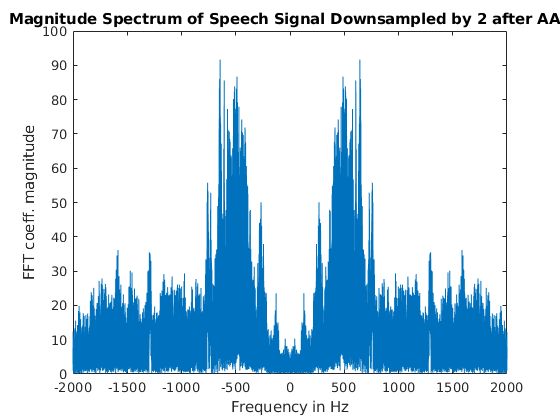

figure();
plot(wSpeech, abs(fft_speechD));
xlabel("Frequency in Hz");
ylabel("FFT coeff. magnitude");
title("Magnitude Spectrum of Speech Signal Downsampled by 2 after AAF");

## Part 3: Equiripple LPF Design

Lowpass Filter with cutoff at $\frac{\pi}{4}$ 

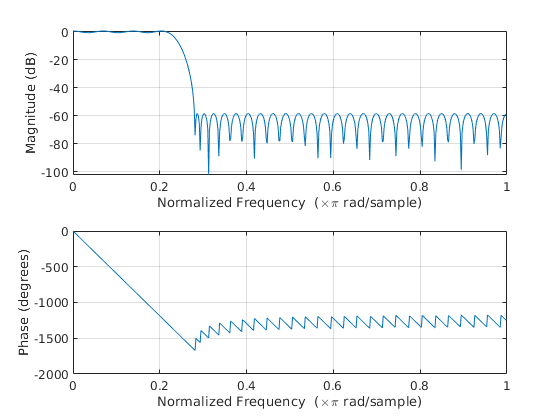

cutoff = [0.22*pi, 0.28*pi];
% Passband and Stopband Ripples in dB
rpass = 1;  
%rstop = -30; 
rstop = -60;    % Vary rstop to see if "stronger" filters have significant impact
filtFreqAudio = cutoff*Fs_audio/(2*pi);
filtFreqSpeech = cutoff*Fs_speech/(2*pi);
a = [1, 0];     % Desired amplitudes at the passband and stopband frequencies
dev = [(10^(rpass/20) - 1)/(10^(rpass/20) + 1), 10^(rstop/20)];
[n, fo, ao, w] = firpmord(filtFreqAudio, a, dev, Fs_audio);
lpfAudio = firpm(n, fo, ao, w);
[n, fo, ao, w] = firpmord(filtFreqSpeech, a, dev, Fs_speech);
lpfSpeech = firpm(n, fo, ao, w);
freqz(lpfAudio);

## Part 4: Fractional Downsampling by Upsamling before Downsampling

In this section, the audio signals are first upsampled by a factor of 3, then multiplied by the LPF and then downsampled by a factor of 4. Here, the LPF behaves like an interpolation filter for the upsampling process and as an Anti-Aliasing Filter for the downsampling process.

#### 4.1 Play Back and Magnitude Spectrum of Upsampled Signal

L = 3;
audioUp = upsample(audio16k, L);
speechUp = upsample(speech8k, L);
%{
playback of upsampled signal: Notice high freq 'ringing' as the signal
is not interpolated.
%}
player1 = audioplayer(audioUp, Fs_audio*L);
player2 = audioplayer(speechUp, Fs_speech*L);
playblocking(player1);
playblocking(player2);

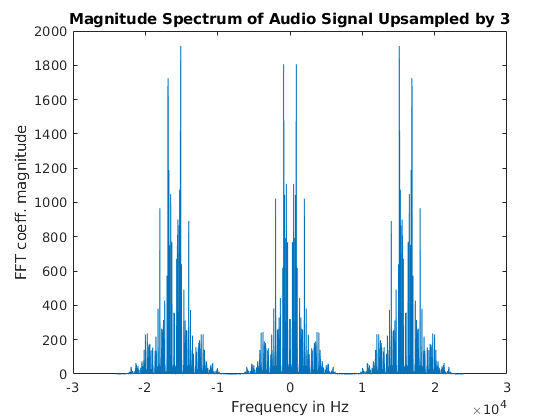

% Magnitude Spectrum of Upsampled Signal
NaudioUp = 2^(ceil(log2(length(audioUp))));
NspeechUp = 2^(ceil(log2(length(speechUp))));
Fs_audioUp = Fs_audio*L;
Fs_speechUp = Fs_speech*L;
fft_audioUp = fftshift(fft(audioUp, NaudioUp));
fft_speechUp = fftshift(fft(speechUp, NspeechUp));
wAudio = linspace(-Fs_audioUp/2, Fs_audioUp/2, NaudioUp);
wSpeech = linspace(-Fs_speechUp/2, Fs_speechUp/2, NspeechUp); 
figure();
plot(wAudio, abs(fft_audioUp));
xlabel("Frequency in Hz");
ylabel("FFT coeff. magnitude");
title("Magnitude Spectrum of Audio Signal Upsampled by 3");

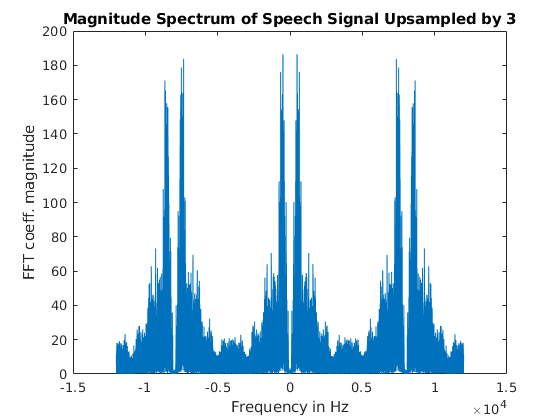

figure();
plot(wSpeech, abs(fft_speechUp));
xlabel("Frequency in Hz");
ylabel("FFT coeff. magnitude");
title("Magnitude Spectrum of Speech Signal Upsampled by 3");

#### 4.2 Play Back and Magnitude Spectrum of Interpolated Signal

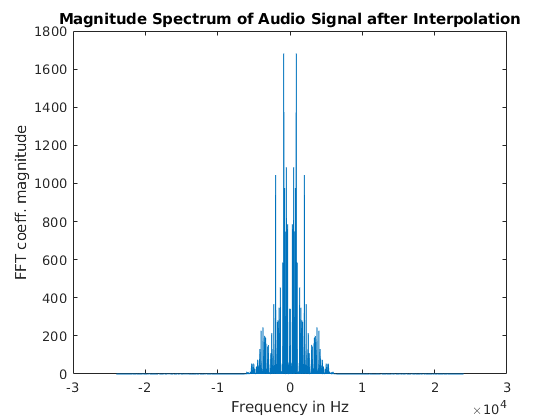

audioUAA = filter(lpfAudio, 1, audioUp);
speechUAA = filter(lpfSpeech, 1, speechUp);
%{
playback of interpolated signal: notice the better sound quality
%}
player1 = audioplayer(audioUAA, Fs_audio*L);
player2 = audioplayer(speechUAA, Fs_speech*L);
playblocking(player1);
playblocking(player2);
% Mag Spectrum of Interpolated Signals
fft_audioUAA = fftshift(fft(audioUAA, NaudioUp));
fft_speechUAA = fftshift(fft(speechUAA, NspeechUp));
figure();
plot(wAudio, abs(fft_audioUAA));
xlabel("Frequency in Hz");
ylabel("FFT coeff. magnitude");
title("Magnitude Spectrum of Audio Signal after Interpolation");

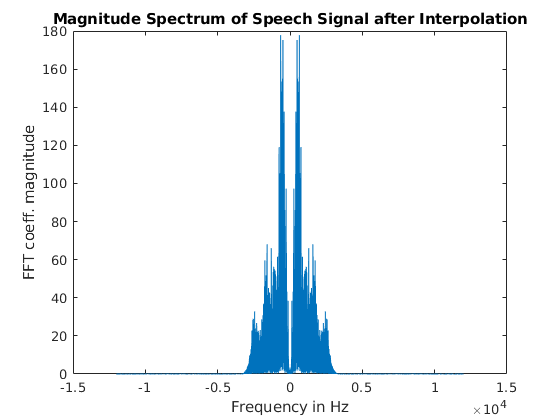

figure();
plot(wSpeech, abs(fft_speechUAA));
xlabel("Frequency in Hz");
ylabel("FFT coeff. magnitude");
title("Magnitude Spectrum of Speech Signal after Interpolation");

#### 4.3 Downsampling Filtered Signal

M = 4;
audioFrac = audioUAA(1:M:end);
speechFrac = speechUAA(1:M:end);
Fs_audioFrac = Fs_audio*(L/M);
Fs_speechFrac = Fs_speech*(L/M);
%{
playback of downsampled signal: fractional downsampling (effective) of 4/3.
Naturally the audio quality for this is the best among Parts 1, 2 and 4.
%}
player1 = audioplayer(audioFrac, Fs_audioFrac);
player2 = audioplayer(speechFrac, Fs_speechFrac);
playblocking(player1);
playblocking(player2);
audiowrite('out/music16k-UAAD.wav', audioFrac, Fs_audioFrac);
audiowrite('out/speech8k-UAAD.wav', speechFrac, Fs_speechFrac);

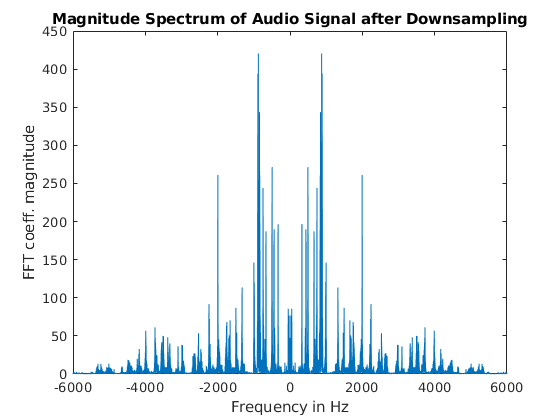

% Mag Spectrum of Fractionally Downsampled Signals
NaudioFrac = 2^(ceil(log2(length(audioFrac))));
NspeechFrac = 2^(ceil(log2(length(speechFrac))));
fft_audioFrac = fftshift(fft(audioFrac, NaudioFrac));
fft_speechFrac = fftshift(fft(speechFrac, NspeechFrac));
wAudio = linspace(-Fs_audioFrac/2, Fs_audioFrac/2, NaudioFrac);
wSpeech = linspace(-Fs_speechFrac/2, Fs_speechFrac/2, NspeechFrac); 
figure();
plot(wAudio, abs(fft_audioFrac));
xlabel("Frequency in Hz");
ylabel("FFT coeff. magnitude");
title("Magnitude Spectrum of Audio Signal after Downsampling");

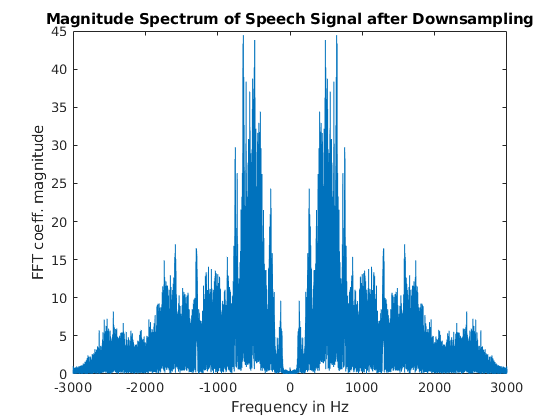

figure();
plot(wSpeech, abs(fft_speechFrac));
xlabel("Frequency in Hz");
ylabel("FFT coeff. magnitude");
title("Magnitude Spectrum of Speech Signal after Downsampling");

## Part 5: Fractional Downsampling by Downsampling before Upsampling

#### 5.1 Play Back and Magnitude Response for Output before Interpolating

M = 4;
L = 3;
audioAA = filter(lpfAudio, 1, audio16k);
speechAA = filter(lpfSpeech, 1, speech8k);
audioD4 = audioAA(1:M:end);
speechD4 = speechAA(1:M:end);
audioAADU = upsample(audioD4, L);
speechAADU = upsample(speechD4, L);
%{
playback of upsampled signal: fractional downsampling (effective) of 4/3.
Naturally the audio quality is poor because performing downsampling first leads to aliasing.
%}
player1 = audioplayer(audioAADU, Fs_audioFrac);
player2 = audioplayer(speechAADU, Fs_speechFrac);
playblocking(player1);
playblocking(player2);

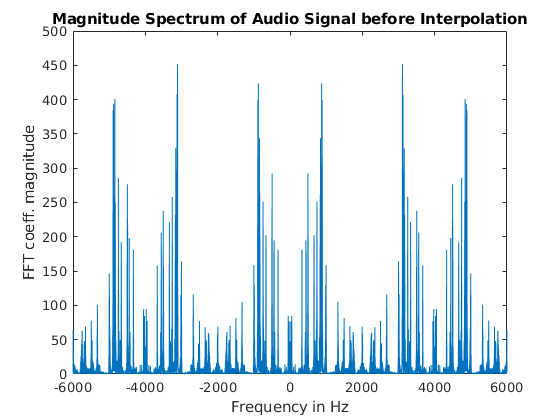

% Mag Spectrum of Fractionally Downsampled Signals
NaudioFrac = 2^(ceil(log2(length(audioAADU))));
NspeechFrac = 2^(ceil(log2(length(speechAADU))));
fft_audioFrac = fftshift(fft(audioAADU, NaudioFrac));
fft_speechFrac = fftshift(fft(speechAADU, NspeechFrac));
wAudio = linspace(-Fs_audioFrac/2, Fs_audioFrac/2, NaudioFrac);
wSpeech = linspace(-Fs_speechFrac/2, Fs_speechFrac/2, NspeechFrac); 
figure();
plot(wAudio, abs(fft_audioFrac));
xlabel("Frequency in Hz");
ylabel("FFT coeff. magnitude");
title("Magnitude Spectrum of Audio Signal before Interpolation");

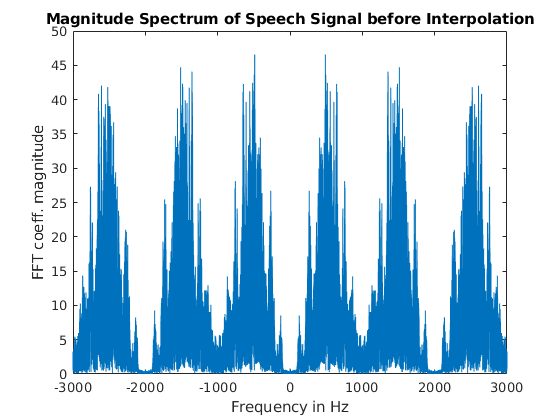

figure();
plot(wSpeech, abs(fft_speechFrac));
xlabel("Frequency in Hz");
ylabel("FFT coeff. magnitude");
title("Magnitude Spectrum of Speech Signal before Interpolation");

#### 5.2 Interpolation Filter Design

bInt = intfilt(L, 3, 1);    % interpolation filter of support 17 
audioOut = filter(bInt, 1, audioAADU);
speechOut = filter(bInt, 1, speechAADU);
%{
playback of interpolated signal: fractional downsampling (effective) of 4/3.
%}
player1 = audioplayer(audioOut, Fs_audioFrac);
player2 = audioplayer(speechOut, Fs_speechFrac);
playblocking(player1);
playblocking(player2);
audiowrite('out/music16k-AADUI.wav', audioOut, Fs_audioFrac);
audiowrite('out/speech8k-AADUI.wav', speechOut, Fs_speechFrac);

**Inference**

The information loss caused by downsampling first is irretrievable, hence the audio quality does not improve significantly upon interpolation of the upsampled signal. Of the downsampled signals from Parts 1 to 5, the following is the order of the observed audio quality in ascending order:

*Note: Only output signals (that have been saved to the out/ directory) of each part are being compared here. Remarks on intermediate signals such as upsampled but not interpolated signals are made as comments in the appropriate code sections. *

- Part 5: Anti-Aliasing -> Downsample by 4 -> Upsample by 3 -> Interpolation 

- Part 1: Downsample by 2 

- Part 2: Anti-Aliasing -> Downsample by 2

- Part 4: Upsample by 3 -> Interpolation-cum-Anti-Aliasing Filtering ->  Downsample by 4

- Original Signal

#### 5.3 Magnitude Response of Interpolating Filter and Output

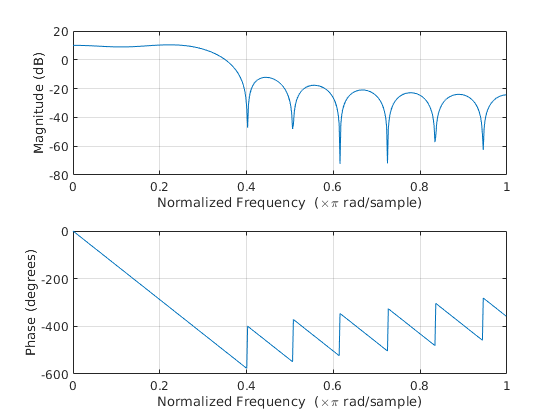

freqz(bInt);    % Frequency Response Spectrum

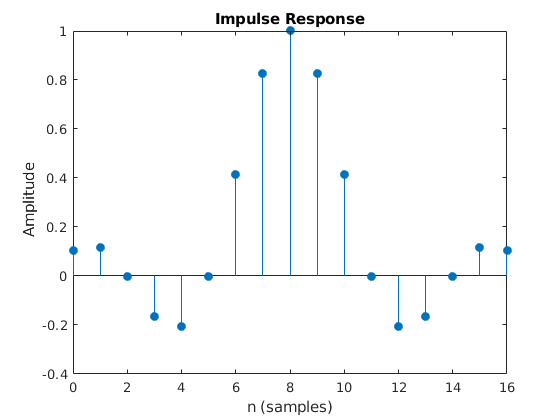

impz(bInt); % Impulse Response of the Interpolation Filter

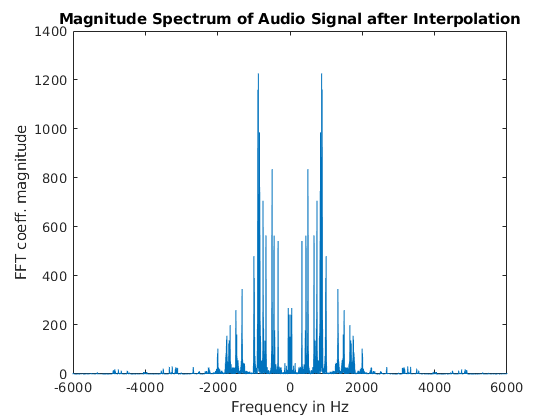

% Mag Spectrum of Interpolated Signals
fft_audioOut = fftshift(fft(audioOut, NaudioFrac));
fft_speechOut = fftshift(fft(speechOut, NspeechFrac));
figure();
plot(wAudio, abs(fft_audioOut));
xlabel("Frequency in Hz");
ylabel("FFT coeff. magnitude");
title("Magnitude Spectrum of Audio Signal after Interpolation");

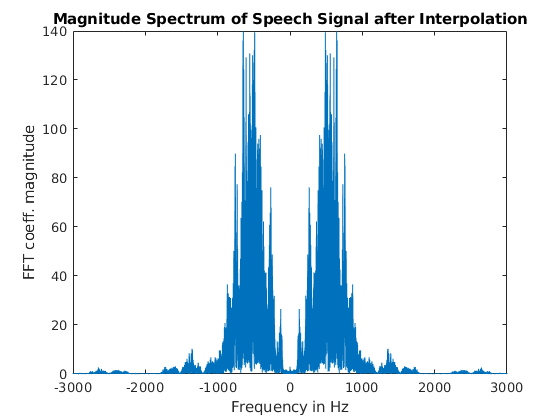

figure();
plot(wSpeech, abs(fft_speechOut));
xlabel("Frequency in Hz");
ylabel("FFT coeff. magnitude");
title("Magnitude Spectrum of Speech Signal after Interpolation");